rampascend04 = readtable("BIOMED AS 2/Ramp Ascend/ramp_asc_lg_trial_01.dat");

% Data lg_t1 cleaning columns fo removing junk data: Annotations and Shank_L
rampascend_clean_table_lg_t1 = removevars(rampascend04,{'Annotation','Annotation_1','Shank_L_1','Shank_L_2'});
rampascend_clean_table_lg_t1 = renamevars(rampascend_clean_table_lg_t1,["Shank_L_3","Shank_L_4","Shank_L_5","Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9","Shank_L_10","Shank_L_11"],["Shank_L_1","Shank_L_2","Shank_L_3","Shank_L_4","Shank_L_5","Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9"]);

% Data filtered using Moving Mean Average method for lg1

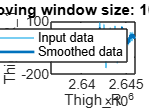

% Filtering for lg1 Thigh_R
% Smooth input data
[filtered_table_lg1_Thigh_R,winSize] = smoothdata(rampascend_clean_table_lg_t1, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Thigh_R_1","Thigh_R_2","Thigh_R_3","Thigh_R_4","Thigh_R_5", ...
    "Thigh_R_6","Thigh_R_7","Thigh_R_8","Thigh_R_9"], ...
    "SamplePoints",rampascend_clean_table_lg_t1.Thigh_R);

% Display results
figure
plot(rampascend_clean_table_lg_t1.Thigh_R,rampascend_clean_table_lg_t1.Thigh_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampascend_clean_table_lg_t1.Thigh_R,filtered_table_lg1_Thigh_R.Thigh_R_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Thigh_R_1","Interpreter","none")
xlabel("Thigh_R","Interpreter","none")

clear winSize

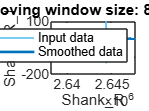

% Filtering for lg1 Shank_R
% Smooth input data
[filtered_table_lg1_Shank_R,winSize2] = smoothdata(filtered_table_lg1_Thigh_R, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Shank_R_1","Shank_R_2","Shank_R_3","Shank_R_4","Shank_R_5", ...
    "Shank_R_6","Shank_R_7","Shank_R_8","Shank_R_9"], ...
    "SamplePoints",filtered_table_lg1_Thigh_R.Shank_R);

% Display results
figure
plot(filtered_table_lg1_Thigh_R.Shank_R,filtered_table_lg1_Thigh_R.Shank_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(filtered_table_lg1_Thigh_R.Shank_R,filtered_table_lg1_Shank_R.Shank_R_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize2));
legend
ylabel("Shank_R_1","Interpreter","none")
xlabel("Shank_R","Interpreter","none")

clear winSize2

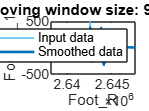

% Filtering for lg1 Foot_R
% Smooth input data
[filtered_table_lg1_Foot_R,winSize3] = smoothdata(filtered_table_lg1_Shank_R, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Foot_R_1","Foot_R_2","Foot_R_3","Foot_R_4","Foot_R_5", ...
    "Foot_R_6","Foot_R_7","Foot_R_8","Foot_R_9"], ...
    "SamplePoints",filtered_table_lg1_Shank_R.Foot_R);

% Display results
figure
plot(filtered_table_lg1_Shank_R.Foot_R,filtered_table_lg1_Shank_R.Foot_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(filtered_table_lg1_Shank_R.Foot_R,filtered_table_lg1_Foot_R.Foot_R_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize3));
legend
ylabel("Foot_R_1","Interpreter","none")
xlabel("Foot_R","Interpreter","none")

clear winSize3

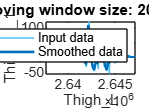

% Filtering for lg1 Thigh_L
% Smooth input data
[filtered_table_lg1_Thigh_L,winSize4] = smoothdata(filtered_table_lg1_Foot_R, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Thigh_L_1","Thigh_L_2","Thigh_L_3","Thigh_L_4","Thigh_L_5", ...
    "Thigh_L_6","Thigh_L_7","Thigh_L_8","Thigh_L_9"], ...
    "SamplePoints",filtered_table_lg1_Foot_R.Thigh_L);

% Display results
figure
plot(filtered_table_lg1_Foot_R.Thigh_L,filtered_table_lg1_Foot_R.Thigh_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(filtered_table_lg1_Foot_R.Thigh_L,filtered_table_lg1_Thigh_L.Thigh_L_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize4));
legend
ylabel("Thigh_L_1","Interpreter","none")
xlabel("Thigh_L","Interpreter","none")

clear winSize4

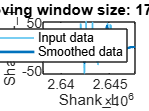

% Filtering for lg1 Shank_L
% Smooth input data
[filtered_table_lg1_Shank_L,winSize5] = smoothdata(filtered_table_lg1_Thigh_L, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Shank_L_1","Shank_L_2","Shank_L_3","Shank_L_4","Shank_L_5", ...
    "Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9"], ...
    "SamplePoints",filtered_table_lg1_Thigh_L.Shank_L);

% Display results
figure
plot(filtered_table_lg1_Thigh_L.Shank_L,filtered_table_lg1_Thigh_L.Shank_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(filtered_table_lg1_Thigh_L.Shank_L,filtered_table_lg1_Shank_L.Shank_L_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize5));
legend
ylabel("Shank_L_1","Interpreter","none")
xlabel("Shank_L","Interpreter","none")

clear winSize5

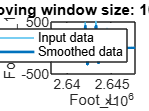

% Filtering for lg1 Foot_L
% Smooth input data
[filtered_table_lg1_Foot_L,winSize6] = smoothdata(filtered_table_lg1_Shank_L, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Foot_L_1","Foot_L_2","Foot_L_3","Foot_L_4","Foot_L_5", ...
    "Foot_L_6","Foot_L_7","Foot_L_8","Foot_L_9"], ...
    "SamplePoints",filtered_table_lg1_Shank_L.Foot_L);

% Display results
figure
plot(filtered_table_lg1_Shank_L.Foot_L,filtered_table_lg1_Shank_L.Foot_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(filtered_table_lg1_Shank_L.Foot_L,filtered_table_lg1_Foot_L.Foot_L_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize6));
legend
ylabel("Foot_L_1","Interpreter","none")
xlabel("Foot_L","Interpreter","none")

clear winSize6

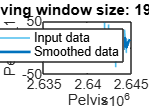

% Filtering for lg1 Pelvis
% Smooth input data
[filtered_table_lg1_Pelvis,winSize7] = smoothdata(filtered_table_lg1_Foot_L, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Pelvis_1","Pelvis_2","Pelvis_3","Pelvis_4","Pelvis_5", ...
    "Pelvis_6","Pelvis_7","Pelvis_8","Pelvis_9"], ...
    "SamplePoints",filtered_table_lg1_Foot_L.Pelvis);

% Display results
figure
plot(filtered_table_lg1_Foot_L.Pelvis,filtered_table_lg1_Foot_L.Pelvis_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(filtered_table_lg1_Foot_L.Pelvis,filtered_table_lg1_Pelvis.Pelvis_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize7));
legend
ylabel("Pelvis_1","Interpreter","none")
xlabel("Pelvis")

clear winSize7

final_filtered_ramp_ascend_lg1 = filtered_table_lg1_Pelvis

final_filtered_ramp_ascend_lg1 = 966x70 table
     Thigh_R      Thigh_R_1    Thigh_R_2    Thigh_R_3    Thigh_R_4    Thigh_R_5    Thigh_R_6    Thigh_R_7    Thigh_R_8    Thigh_R_9     Shank_R      Shank_R_1    Shank_R_2    Shank_R_3    Shank_R_4    Shank_R_5    Shank_R_6    Shank_R_7    Shank_R_8    Shank_R_9      Foot_R      Foot_R_1     Foot_R_2     Foot_R_3     Foot_R_4    Foot_R_5    Foot_R_6    Foot_R_7     Foot_R_8    Foot_R_9     Thigh_L      Thigh_L_1

% Sampling Technique and Feature Extraction for lg1

% Process TR section
TR_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Thigh_R');
 
 
% Process SR section
SR_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Shank_R');
 
 
%Process FR section
FR_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Foot_R');
 
 
%Process TL section
TL_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Thigh_L');
 
 
%Process SL section
SL_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Shank_L');
 
 
%Process FL section
FL_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Foot_L');
 
 
%Process P section
P_tables = Sliding_Window(final_filtered_ramp_ascend_lg1, 'Pelvis');

% Combine results
Var_Names = {'Max', 'Min', 'Mean', 'RMS', 'MaxGrad', 'STD', 'ZC'};
for v = 1:length(Var_Names)
    Combined_Table = [TR_tables.(Var_Names{v}), SR_tables.(Var_Names{v}), FR_tables.(Var_Names{v}), TL_tables.(Var_Names{v}), SL_tables.(Var_Names{v}), FL_tables.(Var_Names{v}), P_tables.(Var_Names{v})];
    assignin('base', ['RampAsc_' Var_Names{v} '_LG1'], Combined_Table);
end